# **Project#1: EngineFaultDB - Feature Extraction**

**Class: Industrial AI & Automation**

**Author: GYEONHEAL AN(21900416), GARMA JIN(21900xxx)**

**Contents**

**1. Data Prepartion**

**2. Data Preprocessing**

-     결측치 확인

-     이상치 확인

-     Correlation Check

-     Min-Max Scaling

**3. Feature Extraction**

- Time-Domain Feature Extraction

- Freq-Domain Feature Extraction

addpath("../../../Library");

## 1. Data Prepartion

clc; clear; close all;

Data_location = "../Datasets/EngineFaultDB_Final.xlsx";
Engine_datasets = readtable(Data_location, 'VariableNamingRule', 'preserve');

% Sampling Freq
fs = 10;
Engine_datasets.Properties

ans =   TableProperties - 속성 있음:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Fault'  'MAP'  'TPS'  'Force'  'Power'  'RPM'  'Consumption L/H'  'Consumption L/100KM'  'Speed'  'CO'  'HC'  'CO2'  'O2'  'Lambda'  'AFR'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: 사용자 지정 속성을 설정하지 않았습니다.
 addprop 및 rmprop을(를) 사용하여 CustomProperties를 수정하십시오.


**Time - Domain Analysis**

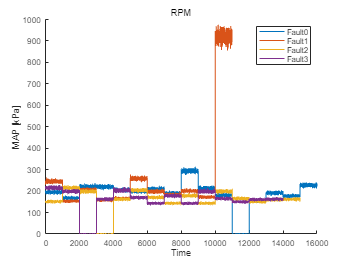

% Data Length Configuration
L0 = height(find(Engine_datasets.Fault == 0)); % Fault 0 : 16,000
L1 = height(find(Engine_datasets.Fault == 1)); % Fault 1 : 10,988
L2 = height(find(Engine_datasets.Fault == 2)); % Fault 2 : 15,000
L3 = height(find(Engine_datasets.Fault == 3)); % Fault 3 : 14,001

figure;
hold on;
plot((1:L0), Engine_datasets(Engine_datasets.Fault == 0, :).HC);
plot((1:L1), Engine_datasets(Engine_datasets.Fault == 1, :).HC);
plot((1:L2), Engine_datasets(Engine_datasets.Fault == 2, :).HC);
plot((1:L3), Engine_datasets(Engine_datasets.Fault == 3, :).HC);
legend('Fault0', 'Fault1', 'Fault2', 'Fault3')
xlabel("Time");
ylabel("MAP [kPa]");
title("RPM");

## 2. Data Preprocessing

### 2.1. 결측치 제거

결측치가 많은 Variables 제거 / MAP, Force, Power, CO, HC

data_fault0 = Engine_datasets(Engine_datasets.Fault == 0, :);
data_fault1 = Engine_datasets(Engine_datasets.Fault == 1, :);
data_fault2 = Engine_datasets(Engine_datasets.Fault == 2, :);
data_fault3 = Engine_datasets(Engine_datasets.Fault == 3, :);

% lowqual_vars = [4; 5; 10; 11];
% 
% data_fault0(:, lowqual_vars) = [];
% data_fault1(:, lowqual_vars) = [];
% data_fault2(:, lowqual_vars) = [];
% data_fault3(:, lowqual_vars) = [];

### 2.2. 노이즈, 이상치 확인 및 제거

Fault1의 데이터셋이 총 10998개까지 있으므로, 1000 개의 Datasets씩, 10000 개의 Datasets들을 처리함.

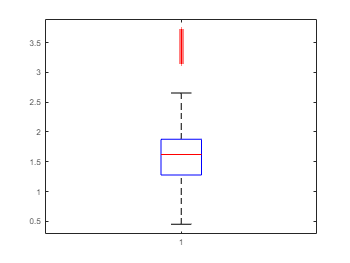

figure;
boxplot(data_fault3.MAP)

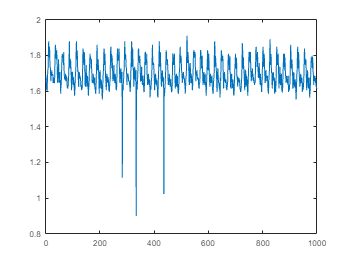

plot(data_fault3.MAP(1:1000,:))

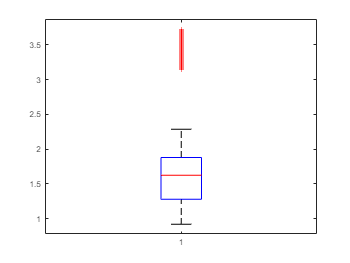

data_faults = {data_fault0, data_fault1, data_fault2, data_fault3};

for i = 1:4
    for t = 1000:1000:10000
        outliers = isoutlier(data_faults{i}(t-999:t, :));
        data_faults{i}(t-999:t, :) = filloutliers(data_faults{i}(t-999:t, :), 'linear');
    end
end

%% Update
data_fault0 = data_faults{1};
data_fault1 = data_faults{2};
data_fault2 = data_faults{3};
data_fault3 = data_faults{4};
datasets = [data_fault0; data_fault1; data_fault2; data_fault3];

boxplot(data_fault3.MAP)

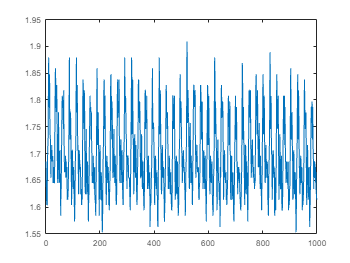

plot(data_fault3.MAP(1:1000,:))

### 2.3. Correlation Check

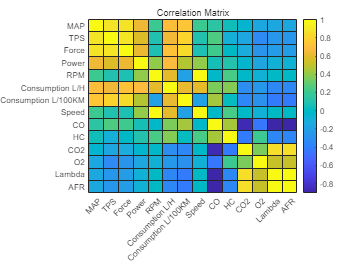

figure;
variable_names = datasets.Properties.VariableNames(2:end);
corr_matrix = corrcoef(table2array(datasets(:, 2:end)));
heatmap(corr_matrix, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Correlation Matrix', 'Colormap', parula);

disp(corr_matrix);

    1.0000    0.8844    0.8803    0.6295    0.2013    0.6979    0.7396    0.2011    0.1343    0.0443   -0.0496   -0.1577   -0.1449   -0.1449
    0.8844    1.0000    0.8916    0.5826    0.0928    0.6480    0.8070    0.0925    0.2538   -0.0987   -0.1641   -0.3309   -0.2619   -0.2619
    0.8803    0.8916    1.0000    0.6214    0.0724    0.7198    0.8484    0.0718    0.2167   -0.0027   -0.1261   -0.2742   -0.2318   -0.2318
    0.6295    0.5826    0.6214    1.0000    0.4035    0.6952    0.4730    0.4058    0.0604    0.1010   -0.0411   -0.1617   -0.0788   -0.0788
    0.2013    0.0928    0.0724    0.4035    1.0000    0.6034   -0.1980    0.9969   -0.0205    0.2362   -0.0156   -0.0801   -0.0038   -0.0037
    0.6979    0.6480    0.7198    0.6952    0.6034    1.0000    0.6141    0.6032    0.3584    0.3748   -0.3133   -0.2521   -0.3479   -0.3478
    0.7396    0.8070    0.8484    0.4730   -0.1980    0.6141    1.0000   -0.1973    0.4413    0.0270   -0.3500   -0.2904   -0.4139   -0.4139
    0.2011   

**연관성 높은 Variables 제거**

corr_threshold = 0.9;
high_corr = abs(corr_matrix) > corr_threshold

high_corr = 14×14 logical 배열
   1   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   1   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   1   0   0   0   0   0   0
   0   0   0   0   0   1   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   1   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   1   0   0   0   1   1
   0   0   0   0   0   0   0   0   0   1   0   0   0   0


high_corr = high_corr - eye(size(high_corr));
[rows, cols] = find(high_corr);

correlated_vars = unique(max(rows, cols));
variable_names = datasets.Properties.VariableNames(2:end);
vars_to_remove = variable_names(correlated_vars);

disp(['Removed variables: ', strjoin(vars_to_remove, ', ')]);

Removed variables: Speed, Lambda, AFR


% 높은 연관성을 가진 데이터 제거
% datasets(:, correlated_vars+1)=[];

### 2.4. Min-Max Scaling

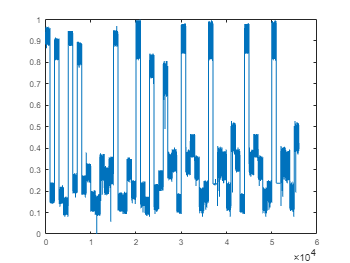

variables = datasets.Properties.VariableNames(2:end);

for i = 1:length(variables)

    datasets.(variables{i}) = normalize(datasets.(variables{i}), 'range');
end
figure;
plot(datasets.MAP);

### 2.5. Data Cutoff

data_fault0 = datasets(1:10000,:);
data_fault1 = datasets(L0+1:L0+10000, :);
data_fault2 = datasets(L0+L1+1:L0+L1+10000, :);
data_fault3 = datasets(L0+L1+L2+1:L0+L1+L2+10000, :);
datasets = [data_fault0; data_fault1; data_fault2; data_fault3];

filename = 'EngineFaultDB_Preprocessed.xlsx';
writetable(datasets, filename);

### 2.x. 각 Fault별 Correlation Check

data_fault0 : 정상

data_fault1 : Rich Mixture 

- 높은 Fuel Pressure

- Incorrect Sensor Performance

- Defective Injector

- Faulty Pressure Regulator

- Clogged Air Filter

- Clogged Fuel return line

--> MAP(Manifold 내부의 압력), TPS,  

data_fault2 : Lean Mixture

- Incorrect Sensor Performance

- Low fuel Pressure

- Defective Injector

- Faulty Pressure Regulator

data_fault3 : Low Voltage

- Worn Spark plugs

- Faulty Ignition Cables

- Defective Coils

- Faulty sensor wiring

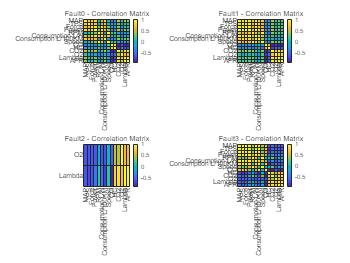

figure;
subplot(2,2,1);
variable_names = data_fault0.Properties.VariableNames(2:end);
corr_matrix_0 = corrcoef(table2array(data_fault0(:, 2:end)));
heatmap(corr_matrix_0, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault0 - Correlation Matrix', 'Colormap', parula);

subplot(2,2,2);
variable_names = data_fault1.Properties.VariableNames(2:end);
corr_matrix_1 = corrcoef(table2array(data_fault1(:, 2:end)));
heatmap(corr_matrix_1, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault1 - Correlation Matrix', 'Colormap', parula);

subplot(2,2,3);
variable_names = data_fault2.Properties.VariableNames(2:end);
corr_matrix_2 = corrcoef(table2array(data_fault2(:, 2:end)));
heatmap(corr_matrix_2, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault2 - Correlation Matrix', 'Colormap', parula);

subplot(2,2,4);
variable_names = data_fault3.Properties.VariableNames(2:end);
corr_matrix_3 = corrcoef(table2array(data_fault3(:, 2:end)));
heatmap(corr_matrix_3, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault3 - Correlation Matrix', 'Colormap', parula);

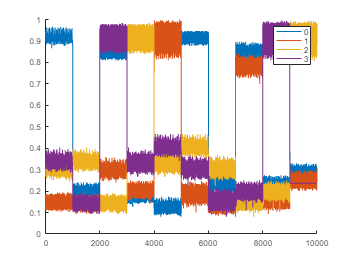

figure;
hold on;
plot(data_fault0.MAP);
plot(data_fault1.MAP);
plot(data_fault2.MAP);
plot(data_fault3.MAP);
hold off
legend('0', '1', '2', '3');

### 3.1. Feature Extraction - Time Domain

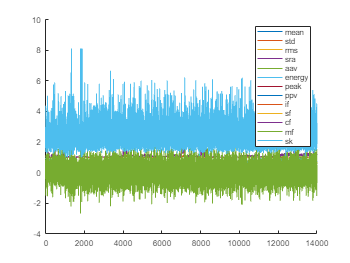

Variables = data_fault1.Properties.VariableNames;
T = 10;

t = 1;
for i = 2:length(Variables)
    for j = T:T:10000
        fault0_time_features(t,:) = timeFeatures(data_fault0{:,i}(j-(9):j,:));
        t = t+1;
    end
end

figure;
hold on;
for i = [1,2,3,4,5,7,8,9,10,11,12,13,14]
    plot(table2array(fault0_time_features(:,i)));
end
legend(fault0_time_features.Properties.VariableNames)

t = 1;
for i = 2:length(Variables)
    for j = T:T:10000
        fault1_time_features(t,:) = timeFeatures(data_fault1{:,i}(j-(9):j,:));
        t = t+1;
    end
end

figure;
hold on;
for i = [1,2,3,4,5,7,8,9,10,11,12,13,14]
    plot(table2array(fault1_time_features(:,i)));
end
legend(fault1_time_features.Properties.VariableNames)

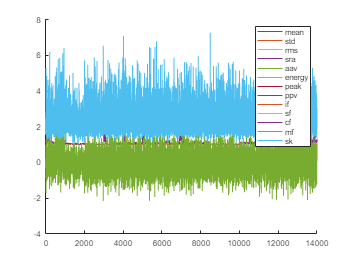

hold off;

t = 1;
for i = 2:length(Variables)
    for j = T:T:10000
        fault2_time_features(t,:) = timeFeatures(data_fault2{:,i}(j-(9):j,:));
        t = t+1;
    end
end

figure;
hold on;
for i = [1,2,3,4,5,7,8,9,10,11,12,13,14]
    plot(table2array(fault2_time_features(:,i)));
end
legend(fault2_time_features.Properties.VariableNames)

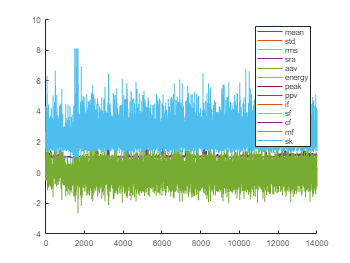

hold off;

%%%%%% 
t = 1;
for i = 2:length(Variables)
    for j = T:T:10000
        fault3_time_features(t,:) = timeFeatures(data_fault3{:,i}(j-(9):j,:));
        t = t+1;
    end
end

figure;
hold on;
for i = [1,2,3,4,5,7,8,9,10,11,12,13,14]
    plot(table2array(fault3_time_features(:,i)));
end
legend(fault3_time_features.Properties.VariableNames)

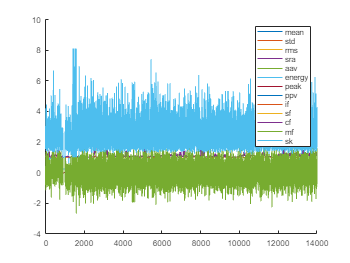

hold off;

datasets = [fault0_time_features; fault1_time_features; fault2_time_features; fault3_time_features];
Fault0_Label = repmat('0', 14000, 1); % "Fault0" 라벨을 140개 생성
Fault1_Label = repmat('1', 14000, 1); % "Fault1" 라벨을 140개 생성
Fault2_Label = repmat('2', 14000, 1); % "Fault2" 라벨을 140개 생성
Fault3_Label = repmat('3', 14000, 1); % "Fault3" 라벨을 140개 생성
Fault = [Fault0_Label; Fault1_Label; Fault2_Label; Fault3_Label];
datasets.Fault = Fault;
datasets = movevars(datasets, 'Fault', 'Before', 1);



X = datasets(:, 2:end);  
Y = datasets.Fault;   

% Test datasets : Train datasets = 2 : 8
cv = cvpartition(Y, 'HoldOut', 0.2);  % 20%는 테스트셋으로 사용

% Training Datasets
X_train = X(training(cv), :);
Y_train = Y(training(cv), :);

% Test Datasets
X_test = X(test(cv), :);
Y_test = Y(test(cv), :);

% Seperate Train datasets and Validation datasets
cv_train = cvpartition(Y_train, 'HoldOut', 0.125);  % 80% 중 1/8은 검증에 사용 (10%)

% Train Datasets
X_train_final = X_train(training(cv_train), :);
Y_train_final = Y_train(training(cv_train), :);

% Validation Datasets
X_val = X_train(test(cv_train), :);
Y_val = Y_train(test(cv_train), :);

svm_model = fitcecoc(X_train_final, Y_train_final);
mlResubErr_svm = resubLoss(svm_model)

mlResubErr_svm = 0.7132

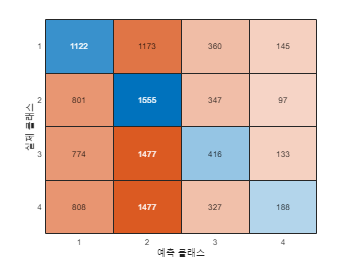


Y_pred = predict(svm_model, X_test);

confusion_matrix = confusionmat(Y_test, Y_pred);

confusionchart(confusion_matrix);


% 정확도 계산
accuracy = sum(Y_pred == Y_test) / length(Y_test);

disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.29295


% X = datasets(:, 2:end);  
% Y = datasets.Fault;   
% 
% % Test datasets : Train datasets = 2 : 8
% cv = cvpartition(Y, 'HoldOut', 0.2);  % 20%는 테스트셋으로 사용
% 
% % Training Datasets
% X_train = X(training(cv), :);
% Y_train = Y(training(cv), :);
% 
% % Test Datasets
% X_test = X(test(cv), :);
% Y_test = Y(test(cv), :);
% 
% % Seperate Train datasets and Validation datasets
% cv_train = cvpartition(Y_train, 'HoldOut', 0.125);  % 80% 중 1/8은 검증에 사용 (10%)
% 
% % Train Datasets
% X_train_final = X_train(training(cv_train), :);
% Y_train_final = Y_train(training(cv_train), :);
% 
% % Validation Datasets
% X_val = X_train(test(cv_train), :);
% Y_val = Y_train(test(cv_train), :);
% 
% svm_model = fitcecoc(X_train_final, Y_train_final);
% mlResubErr_svm = resubLoss(svm_model)
% 
% Y_pred = predict(svm_model, X_test);
% 
% confusion_matrix = confusionmat(Y_test, Y_pred);
% 
% confusionchart(confusion_matrix);
% 
% % 정확도 계산
% accuracy = sum(Y_pred == Y_test) / length(Y_test);
% 
% disp(['Accuracy: ', num2str(accuracy)]);